## 讀取影像

img = imread("D:\Dropbox\wave\In class\4thup\image processing\Original_Images_1\backyard.png");
size(img)

ans =      643            482              3       


讀進來的影像是一個三維矩陣，高643、寬482，然後有三個色彩的 channel

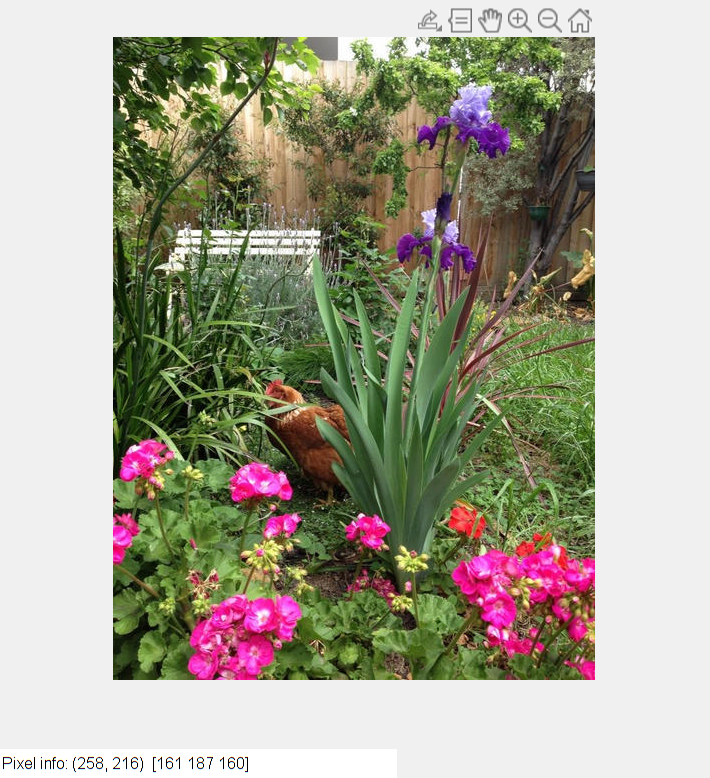

figure;
imshow(img);
impixelinfo;

show 出圖片, ***impixelinfo*** 可以讓滑鼠游標顯示出圖的 info，往右走是 X，往下走是 Y

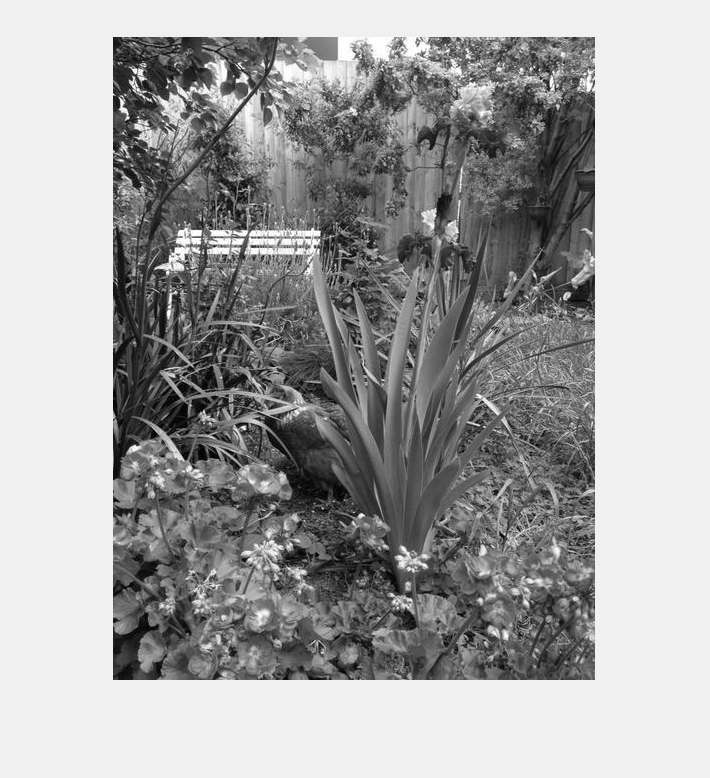

img_gray = rgb2gray(img);
imshow(img_gray);

用 ***rgb2gray*** 可以把彩色的圖片轉成黑白的

## Bit Depth

imfinfo("D:\Dropbox\wave\In class\4thup\image processing\Original_Images_1\backyard.png")

ans = struct with fields:
                  Filename: 'D:\Dropbox\wave\In class\4thup\image processing\Original_Images_1\backyard.png'
               FileModDate: '20-Sep-2022 13:45:01'
                  FileSize: 713173
                    Format: 'png'
             FormatVersion: []
                     Width: 482
                    Height: 643
                  BitDepth: 24
                 ColorType: 'truecolor'
           FormatSignature: [137 80 78 71 13 10 26 10]
                  Colormap: []
                 Histogram: []
             InterlaceType: 'none'
              Transparency: 'none'
    SimpleTransparencyData: []
           BackgroundColor: [1 1 1]
           RenderingIntent: 'perceptual'
            Chromaticities: [293/937 329/1000 16/25 33/100 3/10 3/5 3/20 3/50]
                     Gamma: 9091/20000
               XResolution: 72
               YResolution: 72
            ResolutionUnit: 'unknown'
                   XOffset: []
                   YOffset: []
    

imfinfo("D:\Dropbox\wave\In class\4thup\image processing\Original_Images_1\binary_tools.png")

ans = struct with fields:
                  Filename: 'D:\Dropbox\wave\In class\4thup\image processing\Original_Images_1\binary_tools.png'
               FileModDate: '20-Sep-2022 13:45:01'
                  FileSize: 3100
                    Format: 'png'
             FormatVersion: []
                     Width: 433
                    Height: 548
                  BitDepth: 1
                 ColorType: 'grayscale'
           FormatSignature: [137 80 78 71 13 10 26 10]
                  Colormap: []
                 Histogram: []
             InterlaceType: 'none'
              Transparency: 'none'
    SimpleTransparencyData: []
           BackgroundColor: []
           RenderingIntent: []
            Chromaticities: []
                     Gamma: []
               XResolution: []
               YResolution: []
            ResolutionUnit: []
                   XOffset: []
                   YOffset: []
                OffsetUnit: []
           SignificantBits: []
              Image

imfinfo("D:\Dropbox\wave\In class\4thup\image processing\Original_Images_1\emu.png")

ans = struct with fields:
                  Filename: 'D:\Dropbox\wave\In class\4thup\image processing\Original_Images_1\emu.png'
               FileModDate: '20-Sep-2022 13:45:02'
                  FileSize: 71116
                    Format: 'png'
             FormatVersion: []
                     Width: 331
                    Height: 384
                  BitDepth: 8
                 ColorType: 'indexed'
           FormatSignature: [137 80 78 71 13 10 26 10]
                  Colormap: [64×3 double]
                 Histogram: []
             InterlaceType: 'none'
              Transparency: 'none'
    SimpleTransparencyData: []
           BackgroundColor: []
           RenderingIntent: []
            Chromaticities: []
                     Gamma: []
               XResolution: []
               YResolution: []
            ResolutionUnit: []
                   XOffset: []
                   YOffset: []
                OffsetUnit: []
           SignificantBits: []
              Imag

顏色小知識: 每一個 bit 可表示一種顏色, bit depth 就是用二進位表達一個 channel 有的顏色數量。bit depth = 8 表示一個 channel 有 2^8 個顏色。每個 channel 的 bit depth 被稱為 bits per channel (bpc), 把一個像素所有 channel 的 bit depth 加起來就是一個像素可以表達的顏色數量，叫 bits per pixel (bpp)。

用 ***imfinfo*** 可以 show 出圖片的資訊, 這裡的 Bit Depth 是指 per channel 還是 per pixel 還不大確定, 但我猜應該是 per channel, 因為 true color 的 bit depth 是 24。colortype 有三種類型 [true color, grayscale, indexed]

## Read Indexed Image

[img, img_index] = imread("D:\Dropbox\wave\In class\4thup\image processing\Original_Images_1\emu.png")

img = 384×331 uint8 matrix
   17   23   17   23   25   23   25   26   26   35   43   35   16    6    9   12   21   30   28   23   23   23   23   26   23   26   35   37   37   26   23   33   43   38   30   15   37   46    7   11   18   19   11   40   40   24   32   29   24   11    7    5    2    2    2    2    2    7   11   24   40   40   24   11    7   11   32   38   25   20   10    6   55   49   12    8    7   18   24   24   19   24   24   24   19   38   30   34   46   32   27   38   31   31   38   27   27   14   14   27   31   19   19    7    7   40   11   27   24   40   31   32   31   31   31   24   13    7   41   12    2    7    2    1    1   16   16    3    3    1    6   16   16   10    6   16    6   17   22   12   36   35   26   26   26   15    7   11   11   19   19   27   22   11   14   31   19   14    7    5    5    5    2    2    2    2    2    5    5    5    5   14   30   38   38   17   17   26   26   16   10   17   25   26   15   15   15   12   30   22   17   17   10   25   

img_index =       31/255         31/255         12/85    
      41/255          3/17          49/255   
      46/255         13/51          44/255   
      18/85          10/51           1/5     
      56/255         62/255         22/85    
      56/255         88/255         46/255   
      62/255         21/85          49/255   
      21/85          92/255         67/255   
      67/255         22/85          13/51    
      14/51          73/255          1/3     
       5/17          24/85          67/255   
      79/255        113/255          6/17    
      16/51          88/255         86/255   
      16/51          88/255        103/255   
      83/255         37/85          14/51    
      28/85          31/85          24/85    
       1/3           26/85          71/255   
      91/255         89/255         86/255   
      19/51          23/51          22/51    
      19/51         137/255        112/255   
      32/85          32/85           7/17    
      32/85         10

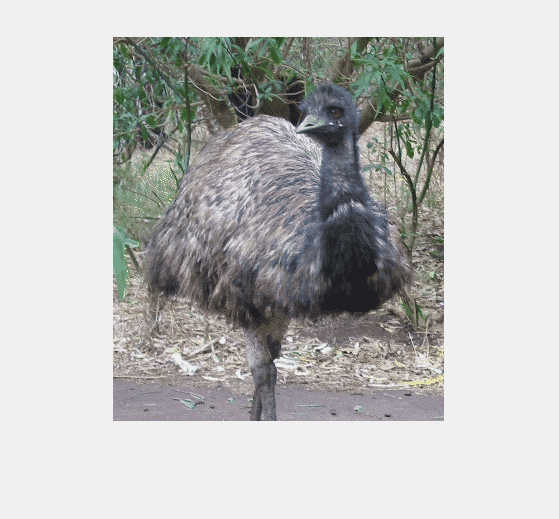

imshow(img, img_index)

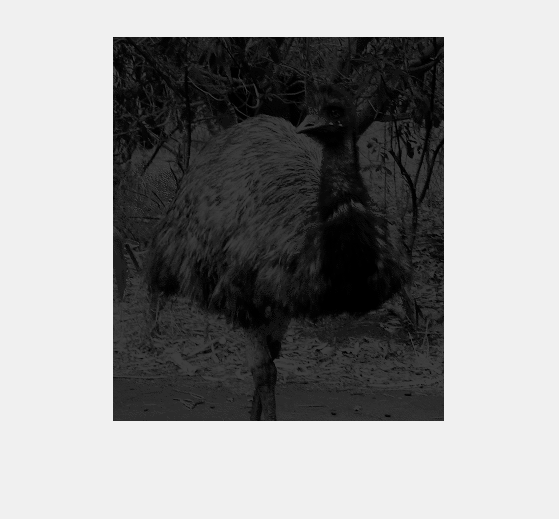

imshow(img)

img_index

img_index =       31/255         31/255         12/85    
      41/255          3/17          49/255   
      46/255         13/51          44/255   
      18/85          10/51           1/5     
      56/255         62/255         22/85    
      56/255         88/255         46/255   
      62/255         21/85          49/255   
      21/85          92/255         67/255   
      67/255         22/85          13/51    
      14/51          73/255          1/3     
       5/17          24/85          67/255   
      79/255        113/255          6/17    
      16/51          88/255         86/255   
      16/51          88/255        103/255   
      83/255         37/85          14/51    
      28/85          31/85          24/85    
       1/3           26/85          71/255   
      91/255         89/255         86/255   
      19/51          23/51          22/51    
      19/51         137/255        112/255   
      32/85          32/85           7/17    
      32/85         10

在讀取 indexed image 的時候, 要連 index 的 map 一起讀進來, show 的時候也要一起 show。如果沒有 map 的話會變黑白的, 原本的顏色會不見。index image 的 index 表每個 row 表示一個顏色, 分別為 RGB, range 從 0~1。

## Double

img = imread("D:\Dropbox\wave\In class\4thup\image processing\Original_Images_1\caribou.jpg");
img_double = double(img)

img_double =      167            172            161            147            146            144            145            155            147            143            147            157            156            147            144            150            136            119            126            145            146            141            138            131            116            120            124            135            136            115            106            122            126            134            129            139            137            125            128            119            133            128            131            143            149            144            140            141            139            142            140            130            132            153            165            156            139            135            117            101            111            134            138            123            130            136    

img_double

img_double =      167            172            161            147            146            144            145            155            147            143            147            157            156            147            144            150            136            119            126            145            146            141            138            131            116            120            124            135            136            115            106            122            126            134            129            139            137            125            128            119            133            128            131            143            149            144            140            141            139            142            140            130            132            153            165            156            139            135            117            101            111            134            138            123            130            136    

在 matlab 裡可以讀取 unit8 或者是 double 兩種數值的 grayscale picture, 可是如果是讀 double 的時候 range 要設成 0~1。上面那個圖原本是 uint8，轉成 double 後因為沒有重新 scale, 所以值全部都大於 1, 跑出來的圖就會是全白。

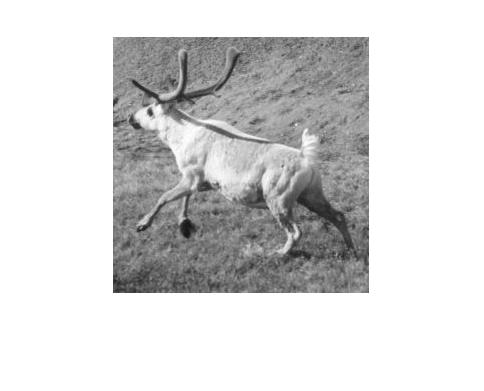

img_d_255 = img_double / 255; imshow(img_d_255)

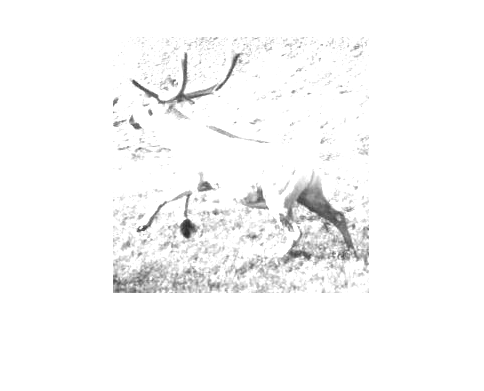

img_d_128 = img_double / 128; imshow(img_d_128)

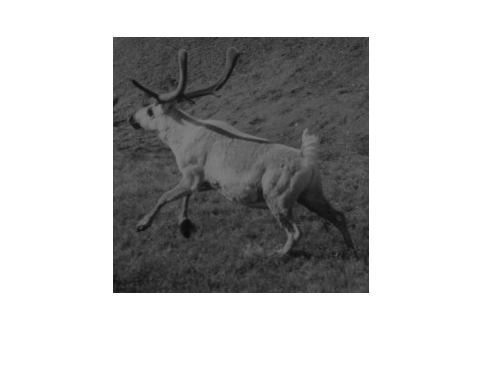

img_d_512 = img_double / 512; imshow(img_d_512)

將 float 的 matrix 除以 255 就會變成原本的顏色，除以 128 就會比原來的白2倍，除以512就會比原來的黑2倍。

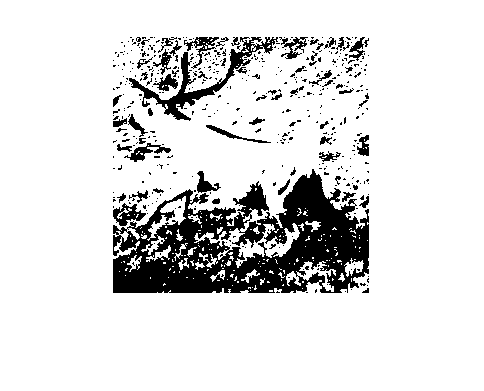

create_index_128 = img > 128; imshow(create_index_128)

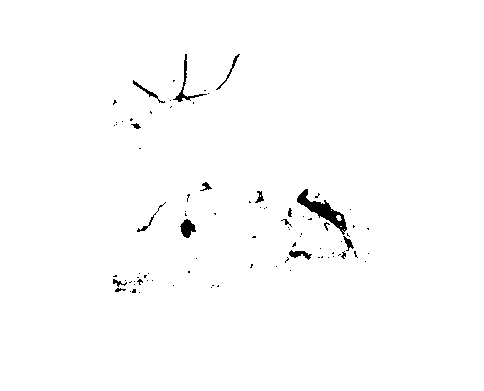

create_index_64 = img > 64; imshow(create_index_64)

用這個方法可以直接創造出 binary image

## Bit Plane

Bit Plane 就是把 grayscale picture 每個 pixel 的 bit 單獨拿出來畫成 8 張 binary image, 越右邊的 bit 越沒意義, 越左邊的 bit 可以把圖的輪廓畫出來。

img = imread("D:\Dropbox\wave\In class\4thup\image processing\Original_Images_1\cameraman.png")

img = 256×256 uint8 matrix
   156   159   158   155   158   156   159   158   157   158   158   159   160   160   160   158   163   161   162   160   164   160   165   163   161   163   161   164   165   162   161   165   165   164   166   165   164   166   167   165   165   164   170   166   167   167   170   168   169   166   169   167   170   169   169   171   169   171   169   171   170   169   173   173   172   171   173   176   174   176   180   179   178   178   181   181   181   177   180   178   179   180   180   180   178   184   181   182   183   182   183   181   182   183   182   185   184   181   181   183   184   183   184   183   186   186   187   184   183   185   185   185   182   183   186   182   184   187   185   188   185   185   186   184   184   182   186   186   185   181   186   182   182   185   183   180   181   182   181   185   182   186   182   181   183   182   181   181   181   179   181   177   180   181   178   178   180   179   180   177   179   180 

bitget(img, 1) % 產生右邊數來第1個 bit plane

ans = 256×256 uint8 matrix
   0   1   0   1   0   0   1   0   1   0   0   1   0   0   0   0   1   1   0   0   0   0   1   1   1   1   1   0   1   0   1   1   1   0   0   1   0   0   1   1   1   0   0   0   1   1   0   0   1   0   1   1   0   1   1   1   1   1   1   1   0   1   1   1   0   1   1   0   0   0   0   1   0   0   1   1   1   1   0   0   1   0   0   0   0   0   1   0   1   0   1   1   0   1   0   1   0   1   1   1   0   1   0   1   0   0   1   0   1   1   1   1   0   1   0   0   0   1   1   0   1   1   0   0   0   0   0   0   1   1   0   0   0   1   1   0   1   0   1   1   0   0   0   1   1   0   1   1   1   1   1   1   0   1   0   0   0   1   0   1   1   0   0   0   0   0   1   0   1   1   1   0   0   0   0   0   0   1   1   1   1   0   1   1   1   1   0   1   0   0   0   0   1   0   1   1   0   0   0   0   0   1   0   0   0   1   0   1   0   1   0   0   0   1   0   1   0   0   0   0   0   0   1   1   1   1   1   1   0   1   1   0   1   1   0   1   0   0   1   1   0   0   1 

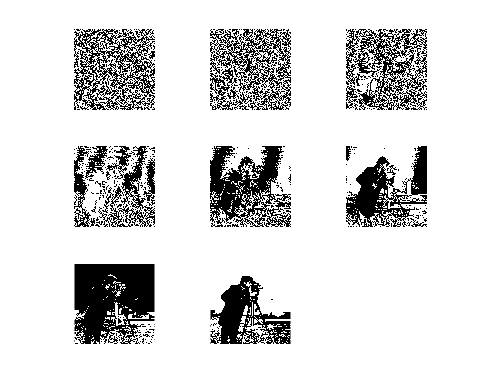


for i = 1:8
    subplot(3, 3, i);
    imshow(logical(bitget(img, i)));
end

## Spatial Resolution

一張圖片裡面的像素個數稱為空間解析度 (Spatial Resolution), 空間解析度越高, 圖片越清楚, 用 ***imresize*** 可以調整圖片大小。如果把圖片邊常都變 1/2, 就會每隔一行抽掉一行, 剩下一半的行數。然後放大 2 倍就會複製隔壁的行變回原來的數量, 因此這樣解析度就會變一半

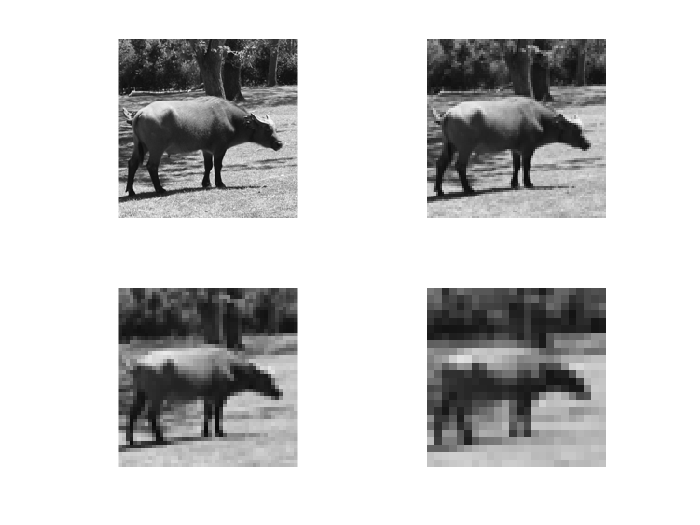

img = imread("D:\Dropbox\wave\In class\4thup\image processing\Original_Images_1\buffalo.png");
for i = 1:4
    subplot(2, 2, i);
    imshow(imresize(imresize(img, 1/2^i), 2^i, "nearest"))
end

上面的圖分別就是原本解析度的 1/4, 1/16, 1/64, 1/128 倍